load('all_rats_sham_P1.mat')
load('all_rats_sham_P2.mat')
load('all_rats_et1_P1.mat')
load('all_rats_et1_P2.mat')

% verificare omogeneità della varianza --> h=1 se non vengono da
% distribuzioni normali con la stessa varianza, h=0 se l'h0 viene
% 'accettata' nel senso che c'è la possibilità che vengano da distribuzioni
% normali con stessa varianza ma questo non è certo ---> p=probabilità
% della null ipotesi
[h,p] = vartest2(all_rats_sham_P1,all_rats_et1_P1)

h = 1

p = 0.0013

[h,p] = vartest2(all_rats_sham_P2,all_rats_et1_P2)

h = 0

p = 0.9739


% verificare differenza statistica tra le curve--> h=1 distribuzioni sono
% diverse statisticamente
[h,p] = ttest2(all_rats_sham_P1,all_rats_et1_P1)

h = 0

p = 0.6300

[h,p] = ttest2(all_rats_sham_P2,all_rats_et1_P2)

h = 0

p = 0.6987

% calcolo media e mediane di tutti e 4 i casi
mean_all_rats_sham_P1=mean(all_rats_sham_P1);
median_all_rats_sham_P1=median(all_rats_sham_P1);

mean_all_rats_sham_P2=mean(all_rats_sham_P2);
median_all_rats_sham_P2=median(all_rats_sham_P2);

mean_all_rats_et1_P1=mean(all_rats_et1_P1);
median_all_rats_et1_P1=median(all_rats_et1_P1);

mean_all_rats_et1_P2=mean(all_rats_et1_P2);
median_all_rats_et1_P2=median(all_rats_et1_P2);

bin_width=10;

%% istogramma p1 di tutti gli sham
h_p1_sham=histogram(all_rats_sham_P1,'Normalization','probability','BinWidth',bin_width,'BinLimits',[-200 200])

h_p1_sham =   Histogram with properties:

             Data: [48×1 double]
           Values: [0 0 0 0 0 0 0 0 0 0 0 0 0.0208 0.0417 0.1667 0.0417 0.0625 0.0833 0.0417 0.0833 0.1042 0.0833 0.0417 0.0417 0 0.0417 0.0208 0.0208 0.0417 0.0208 0 0 0.0208 0.0208 0 0 0 0 0 0]
          NumBins: 40
         BinEdges: [-200 -190 -180 -170 -160 -150 -140 -130 -120 -110 -100 -90 -80 -70 -60 -50 -40 -30 -20 -10 0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]
         BinWidth: 10
        BinLimits: [-200 200]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


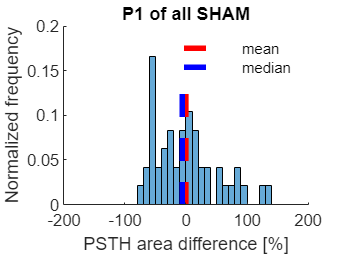

hold on
stem(mean_all_rats_sham_P1,max(h_p1_sham.Values),LineStyle="--",Marker="none",LineWidth=3,Color=[1 0 0])
stem(median_all_rats_sham_P1,max(h_p1_sham.Values),LineStyle="--",Marker="none",LineWidth=3,Color=[0 0 1])
hold off
xlim([-200 200])
title('P1 of all SHAM')
xlabel('PSTH area difference [%]')
ylabel('Normalized frequency')
box off
legend('','mean','median')
legend box off


num_bins=h_p1_sham.NumBins;
prob_p1_sham=h_p1_sham.Values;


%% istogramma p2 di tutti gli sham
h_p2_sham=histogram(all_rats_sham_P2,'Normalization','probability','BinWidth',bin_width,'BinLimits',[-200 200])

h_p2_sham =   Histogram with properties:

             Data: [48×1 double]
           Values: [0 0 0 0 0 0 0 0 0 0 0 0.0417 0 0.0208 0.1875 0.1458 0.1250 0.0833 0.0833 0.1042 0.1042 0.0417 0 0.0208 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
          NumBins: 40
         BinEdges: [-200 -190 -180 -170 -160 -150 -140 -130 -120 -110 -100 -90 -80 -70 -60 -50 -40 -30 -20 -10 0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]
         BinWidth: 10
        BinLimits: [-200 200]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


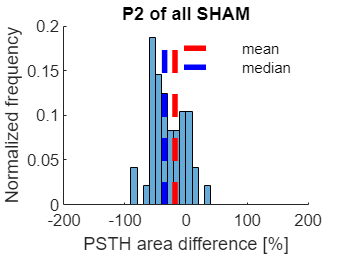

hold on
stem(mean_all_rats_sham_P2,max(h_p2_sham.Values),LineStyle="--",Marker="none",LineWidth=3,Color=[1 0 0])
stem(median_all_rats_sham_P2,max(h_p2_sham.Values),LineStyle="--",Marker="none",LineWidth=3,Color=[0 0 1])
hold off
xlim([-200 200])
title('P2 of all SHAM')
xlabel('PSTH area difference [%]')
ylabel('Normalized frequency')
box off
legend('','mean','median')
legend box off


prob_p2_sham=h_p2_sham.Values;


%% istogramma p1 di tutti gli et1
h_p1_et1=histogram(all_rats_et1_P1,'Normalization','probability','BinWidth',bin_width,'BinLimits',[-200 200])

h_p1_et1 =   Histogram with properties:

             Data: [48×1 double]
           Values: [0 0 0 0 0 0 0 0 0 0 0 0.1042 0.0417 0.0625 0.0417 0.0208 0.1667 0.1458 0.0417 0.0208 0.0208 0 0 0.0208 0.0208 0.0208 0.0625 0 0.0417 0.0417 0 0.0208 0 0.0208 0.0208 0 0 0 0 0.0208]
          NumBins: 40
         BinEdges: [-200 -190 -180 -170 -160 -150 -140 -130 -120 -110 -100 -90 -80 -70 -60 -50 -40 -30 -20 -10 0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]
         BinWidth: 10
        BinLimits: [-200 200]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


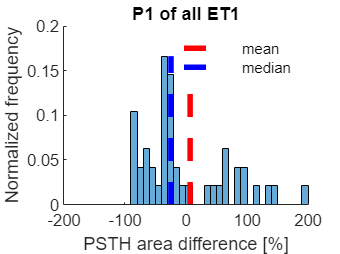

hold on
stem(mean_all_rats_et1_P1,max(h_p1_et1.Values),LineStyle="--",Marker="none",LineWidth=3,Color=[1 0 0])
stem(median_all_rats_et1_P1,max(h_p1_et1.Values),LineStyle="--",Marker="none",LineWidth=3,Color=[0 0 1])
hold off
xlim([-200 200])
title('P1 of all ET1')
xlabel('PSTH area difference [%]')
ylabel('Normalized frequency')
box off
legend('','mean','median')
legend box off


prob_p1_et1=h_p1_et1.Values;


%% istogramma p2 di tutti gli et1
h_p2_et1=histogram(all_rats_et1_P2,'Normalization','probability','BinWidth',bin_width,'BinLimits',[-200 200])

h_p2_et1 =   Histogram with properties:

             Data: [48×1 double]
           Values: [0 0 0 0 0 0 0 0 0 0 0.0625 0.2708 0 0 0 0 0.0833 0 0.0417 0.0833 0.0208 0.0833 0.1042 0.0625 0.0625 0.0208 0.0208 0.0208 0 0 0.0208 0 0.0417 0 0 0 0 0 0 0]
          NumBins: 40
         BinEdges: [-200 -190 -180 -170 -160 -150 -140 -130 -120 -110 -100 -90 -80 -70 -60 -50 -40 -30 -20 -10 0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]
         BinWidth: 10
        BinLimits: [-200 200]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


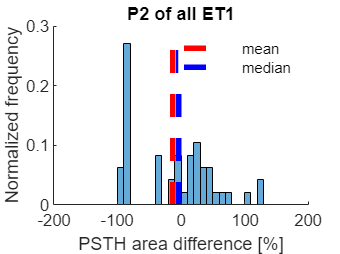

hold on
stem(mean_all_rats_et1_P2,max(h_p2_et1.Values),LineStyle="--",Marker="none",LineWidth=3,Color=[1 0 0])
stem(median_all_rats_et1_P2,max(h_p2_et1.Values),LineStyle="--",Marker="none",LineWidth=3,Color=[0 0 1])
hold off
xlim([-200 200])
title('P2 of all ET1')
xlabel('PSTH area difference [%]')
ylabel('Normalized frequency')
box off
legend('','mean','median')
legend box off


prob_p2_et1=h_p2_et1.Values;

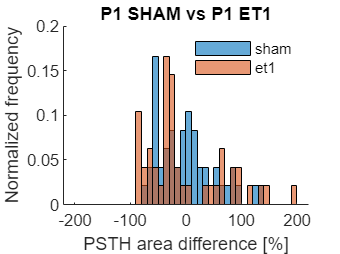

% istogrammi insieme per confronto
histogram(all_rats_sham_P1,'Normalization','probability','BinWidth',bin_width,'BinLimits',[-200 200])
hold on
histogram(all_rats_et1_P1,'Normalization','probability','BinWidth',bin_width,'BinLimits',[-200 200])
hold off
title('P1 SHAM vs P1 ET1')
xlabel('PSTH area difference [%]')
ylabel('Normalized frequency')
box off
legend('sham','et1')
legend box off

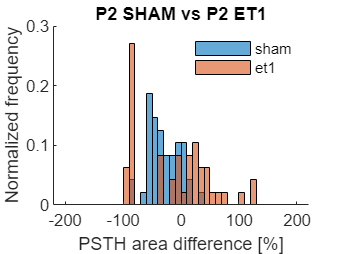



histogram(all_rats_sham_P2,'Normalization','probability','BinWidth',bin_width,'BinLimits',[-200 200])
hold on
histogram(all_rats_et1_P2,'Normalization','probability','BinWidth',bin_width,'BinLimits',[-200 200])
hold off
title('P2 SHAM vs P2 ET1')
xlabel('PSTH area difference [%]')
ylabel('Normalized frequency')
box off
legend('sham','et1')
legend box off

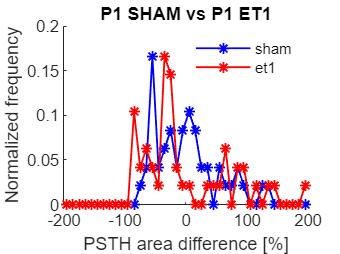

% istogrammi con linea insieme per confronto
x_axis=linspace(-200+bin_width/2,200-bin_width/2,num_bins);

figure
plot(x_axis,prob_p1_sham,'*','color','b',LineStyle='-',LineWidth=1)
hold on
plot(x_axis,prob_p1_et1,'*','color','r',LineStyle='-',LineWidth=1)
hold off
title('P1 SHAM vs P1 ET1')
xlabel('PSTH area difference [%]')
ylabel('Normalized frequency')
box off
legend('sham','et1')
legend box off

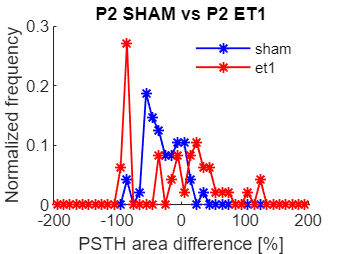


figure
plot(x_axis,prob_p2_sham,'*','color','b',LineStyle='-',LineWidth=1)
hold on
plot(x_axis,prob_p2_et1,'*','color','r',LineStyle='-',LineWidth=1)
hold off
title('P2 SHAM vs P2 ET1')
xlabel('PSTH area difference [%]')
ylabel('Normalized frequency')
box off
legend('sham','et1')
legend box off

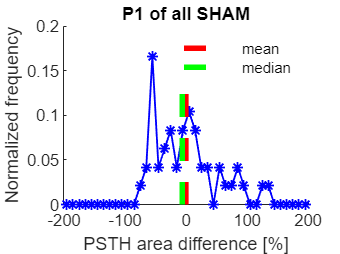

%istogramma P1 sham con linee per pp
figure
plot(x_axis,prob_p1_sham,'*','color','b',LineStyle='-',LineWidth=1)
title('P1 of all SHAM')
xlabel('PSTH area difference [%]')
ylabel('Normalized frequency')
box off
hold on
stem(mean_all_rats_sham_P1,max(prob_p1_sham),LineStyle="--",Marker="none",LineWidth=3,Color=[1 0 0])
stem(median_all_rats_sham_P1,max(prob_p1_sham),LineStyle="--",Marker="none",LineWidth=3,Color=[0 1 0])
hold off
legend('','mean','median')
legend box off

## Bootstrapping from difference of areas 

rng(1)
bin_width_boot=5;

% sham
boot_sham = bootstrp(100000,@(x)[mean(x) median(x)],[all_rats_sham_P1 all_rats_sham_P2])';

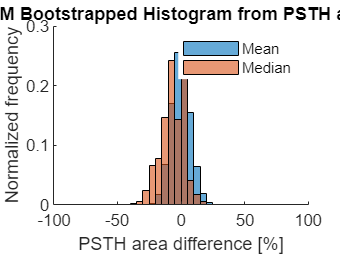

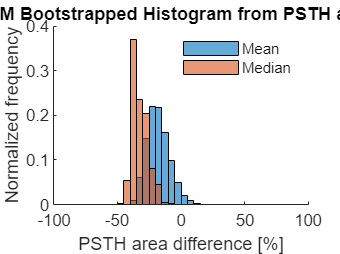

for i=1:2
    j=i+2;

    figure
    if mod(i,2) == 0
        ttl2=sprintf('P2');
    else
        ttl2=sprintf('P1');
    end

    histogram(boot_sham(i,:),'Normalization','probability','BinWidth',bin_width_boot,'BinLimits',[-100 100])
    hold on
    histogram(boot_sham(j,:),'Normalization','probability','BinWidth',bin_width_boot,'BinLimits',[-100 100])
    hold off
    xlim([-100 100])
    title(strcat(ttl2,{' of all SHAM'},{' Bootstrapped Histogram from PSTH areas difference'}))
    xlabel('PSTH area difference [%]')
    ylabel('Normalized frequency')
    legend('Mean', 'Median')
    legend boxoff
    box off
end

% et1
boot_et1 = bootstrp(100000,@(x)[mean(x) median(x)],[all_rats_et1_P1 all_rats_et1_P2])';

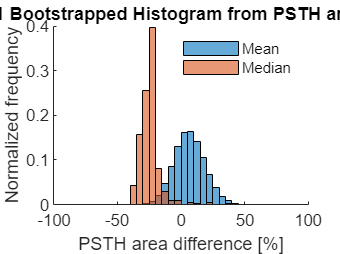

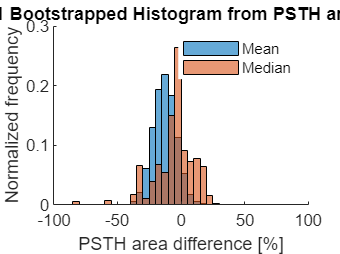

for i=1:2
    j=i+2;

    figure
    if mod(i,2) == 0
        ttl2=sprintf('P2');
    else
        ttl2=sprintf('P1');
    end

    histogram(boot_et1(i,:),'Normalization','probability','BinWidth',bin_width_boot,'BinLimits',[-100 100])
    hold on
    histogram(boot_et1(j,:),'Normalization','probability','BinWidth',bin_width_boot,'BinLimits',[-100 100])
    hold off
    xlim([-100 100])
    title(strcat(ttl2,{' of all ET1'},{' Bootstrapped Histogram from PSTH areas difference'}))
    xlabel('PSTH area difference [%]')
    ylabel('Normalized frequency')
    legend('Mean', 'Median')
    legend boxoff
    box off
end

## Confronto di boot di medie di P1 in sham ed et1

h_boot_sham_p1_mean=histogram(boot_sham(1,:),'Normalization','probability','BinWidth',bin_width_boot,'BinLimits',[-100 100])

h_boot_sham_p1_mean =   Histogram with properties:

             Data: [-6.2839 -4.0226 1.5948 -7.7298 -0.8778 1.2576 3.6000 9.9444 -16.3052 18.4801 0.1953 -3.3448 1.1768 4.8008 -5.6516 -4.4470 -2.8638 4.3549 -0.8824 -3.7998 -0.3118 4.9005 2.8198 -14.4636 1.8136 8.0693 -8.5073 2.6934 -2.1425 -7.4551 … ]
           Values: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 9.0000e-05 0.0022 0.0164 0.0671 0.1698 0.2558 0.2467 0.1550 0.0636 0.0189 0.0039 4.8000e-04 8.0000e-05 0 0 0 0 0 0 0 0 0 0 0 0 0]
          NumBins: 40
         BinEdges: [-100 -95 -90 -85 -80 -75 -70 -65 -60 -55 -50 -45 -40 -35 -30 -25 -20 -15 -10 -5 0 5 10 15 20 25 30 35 40 45 50 55 60 65 70 75 80 85 90 95 100]
         BinWidth: 5
        BinLimits: [-100 100]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show 

prob_boot_sham_p1_mean=h_boot_sham_p1_mean.Values;
hold on
h_boot_et1_p1_mean=histogram(boot_et1(1,:),'Normalization','probability','BinWidth',bin_width_boot,'BinLimits',[-100 100])

h_boot_et1_p1_mean =   Histogram with properties:

             Data: [-4.6002 3.0934 2.3801 19.6444 28.3901 -6.0632 21.7810 7.7274 5.4694 0.9613 17.8341 35.1937 -15.4137 -16.6851 -9.6854 -12.4186 11.5054 14.0251 8.5543 23.9468 4.3744 36.9796 4.8784 33.4290 12.7452 5.3473 4.6852 31.9618 -15.0806 … ]
           Values: [0 0 0 0 0 0 0 0 0 0 0 0 2.0000e-05 3.5000e-04 0.0014 0.0068 0.0204 0.0471 0.0864 0.1293 0.1622 0.1639 0.1422 0.1052 0.0677 0.0371 0.0180 0.0080 0.0027 7.8000e-04 2.2000e-04 9.0000e-05 2.0000e-05 0 0 0 0 0 0 0]
          NumBins: 40
         BinEdges: [-100 -95 -90 -85 -80 -75 -70 -65 -60 -55 -50 -45 -40 -35 -30 -25 -20 -15 -10 -5 0 5 10 15 20 25 30 35 40 45 50 55 60 65 70 75 80 85 90 95 100]
         BinWidth: 5
        BinLimits: [-100 100]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show 

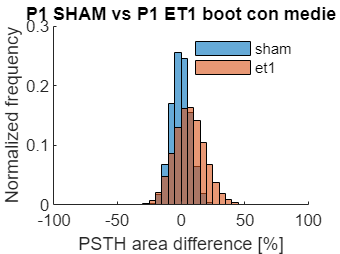

prob_boot_et1_p1_mean=h_boot_et1_p1_mean.Values;
num_bins_boot=h_boot_et1_p1_mean.NumBins;
hold off
xlim([-100 100])
title('P1 SHAM vs P1 ET1 boot con medie')
xlabel('PSTH area difference [%]')
ylabel('Normalized frequency')
legend('sham', 'et1')
legend boxoff
box off

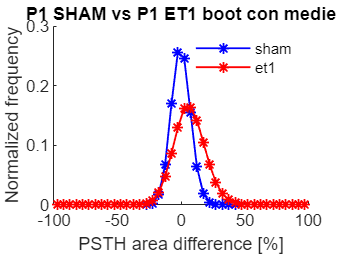


% istogramma a linee
x_axis_boot=linspace(-100+bin_width_boot/2,100-bin_width_boot/2,num_bins_boot);

figure
plot(x_axis_boot,prob_boot_sham_p1_mean,'*','color','b',LineStyle='-',LineWidth=1)
hold on
plot(x_axis_boot,prob_boot_et1_p1_mean,'*','color','r',LineStyle='-',LineWidth=1)
hold off
title('P1 SHAM vs P1 ET1 boot con medie')
xlabel('PSTH area difference [%]')
ylabel('Normalized frequency')
box off
legend('sham','et1')
legend box off

## Confronto di boot di medie di P2 in sham ed et1

h_boot_sham_p2_mean=histogram(boot_sham(3,:),'Normalization','probability','BinWidth',bin_width_boot,'BinLimits',[-100 100])

h_boot_sham_p2_mean =   Histogram with properties:

             Data: [-8.9034 -10.4692 -6.1494 -24.7008 -14.7517 3.6507 1.1396 3.6507 -22.9634 17.8382 -6.1494 4.3692 6.6882 -3.7326 -7.1950 -22.9634 -1.2772 4.3692 -6.8123 1.1396 -11.5147 -6.8123 -20.7982 -26.2191 -11.5147 3.6507 -18.1684 -3.0697 … ]
           Values: [0 0 0 0 0 0 0 0 0 0 1.0000e-05 1.8000e-04 0.0012 0.0059 0.0244 0.0662 0.0768 0.1467 0.2418 0.1435 0.2306 0.0405 0.0162 0.0057 1.8000e-04 3.0000e-05 3.0000e-05 1.0000e-05 0 0 0 0 0 0 0 0 0 0 0 0]
          NumBins: 40
         BinEdges: [-100 -95 -90 -85 -80 -75 -70 -65 -60 -55 -50 -45 -40 -35 -30 -25 -20 -15 -10 -5 0 5 10 15 20 25 30 35 40 45 50 55 60 65 70 75 80 85 90 95 100]
         BinWidth: 5
        BinLimits: [-100 100]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show 

prob_boot_sham_p2_mean=h_boot_sham_p2_mean.Values;
hold on
h_boot_et1_p2_mean=histogram(boot_et1(3,:),'Normalization','probability','BinWidth',bin_width_boot,'BinLimits',[-100 100])

h_boot_et1_p2_mean =   Histogram with properties:

             Data: [-25.6718 -34.0762 -27.4970 -23.4241 -19.5612 -31.9579 -19.5612 -29.1850 -22.4887 -30.5714 -21.5350 36.7500 -38.7864 -25.5347 -35.4384 -35.4384 -20.2875 -23.2059 -27.3599 -22.7069 -19.5612 -15.6205 -23.7622 -7.7870 -24.2612 … ]
           Values: [0 0 0 0 0 0 0 0 0 3.0000e-05 4.0000e-05 5.0000e-04 0.0432 0.1578 0.2554 0.3971 0.0817 0.0298 0.0082 0.0098 0 0.0046 0.0022 3.7000e-04 0.0034 1.3000e-04 0 0.0033 0.0010 5.5000e-04 4.2000e-04 2.0000e-04 1.8000e-04 8.0000e-05 0 0 0 0 … ]
          NumBins: 40
         BinEdges: [-100 -95 -90 -85 -80 -75 -70 -65 -60 -55 -50 -45 -40 -35 -30 -25 -20 -15 -10 -5 0 5 10 15 20 25 30 35 40 45 50 55 60 65 70 75 80 85 90 95 100]
         BinWidth: 5
        BinLimits: [-100 100]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show 

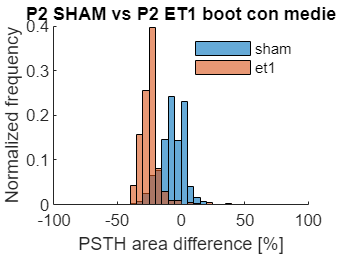

prob_boot_et1_p2_mean=h_boot_et1_p2_mean.Values;
hold off
xlim([-100 100])
title('P2 SHAM vs P2 ET1 boot con medie')
xlabel('PSTH area difference [%]')
ylabel('Normalized frequency')
legend('sham', 'et1')
legend boxoff
box off

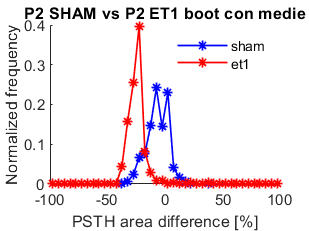


% istogramma lineare
figure
plot(x_axis_boot,prob_boot_sham_p2_mean,'*','color','b',LineStyle='-',LineWidth=1)
hold on
plot(x_axis_boot,prob_boot_et1_p2_mean,'*','color','r',LineStyle='-',LineWidth=1)
hold off
title('P2 SHAM vs P2 ET1 boot con medie')
xlabel('PSTH area difference [%]')
ylabel('Normalized frequency')
box off
legend('sham','et1')
legend box off

## Confronto di boot di mediane di P1 in sham ed et1

h_boot_sham_p1_median=histogram(boot_sham(2,:),'Normalization','probability','BinWidth',bin_width_boot,'BinLimits',[-100 100])

h_boot_sham_p1_median =   Histogram with properties:

             Data: [-16.7020 -31.3341 -28.4026 -28.5283 -34.2712 -38.1226 -8.6948 -7.3478 -21.0604 -7.2493 -21.4158 -24.2991 -18.8081 -9.7005 -20.5345 -23.1256 -27.7430 -18.2897 -11.6953 -22.3977 -15.3342 -32.2523 -21.3958 -9.7853 -23.4602 -6.5784 … ]
           Values: [0 0 0 0 0 0 0 0 0 0 0 2.6000e-04 0.0096 0.0606 0.1479 0.2193 0.2182 0.1622 0.0988 0.0501 0.0209 0.0082 0.0028 8.0000e-04 1.9000e-04 5.0000e-05 3.0000e-05 0 0 0 0 0 0 0 0 0 0 0 0 0]
          NumBins: 40
         BinEdges: [-100 -95 -90 -85 -80 -75 -70 -65 -60 -55 -50 -45 -40 -35 -30 -25 -20 -15 -10 -5 0 5 10 15 20 25 30 35 40 45 50 55 60 65 70 75 80 85 90 95 100]
         BinWidth: 5
        BinLimits: [-100 100]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show 

prob_boot_sham_p1_median=h_boot_sham_p1_median.Values;
hold on
h_boot_et1_p1_median=histogram(boot_et1(2,:),'Normalization','probability','BinWidth',bin_width_boot,'BinLimits',[-100 100])

h_boot_et1_p1_median =   Histogram with properties:

             Data: [-22.5300 -12.2563 -19.6377 0.2423 -6.9571 -18.5168 7.9548 -19.9004 -15.8493 -19.9915 -11.5056 -6.3811 -28.3491 -24.3635 -16.8359 -18.9906 -10.4557 -13.1740 -7.1620 -7.1200 -1.7228 -6.4562 0.5596 -12.0435 -6.4685 -19.9406 -12.7030 … ]
           Values: [0 0 0 0 0 0 0 0 0 1.0000e-05 7.0000e-05 8.0000e-04 0.0052 0.0203 0.0606 0.1295 0.1935 0.2189 0.1830 0.1133 0.0517 0.0177 0.0044 8.9000e-04 1.8000e-04 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
          NumBins: 40
         BinEdges: [-100 -95 -90 -85 -80 -75 -70 -65 -60 -55 -50 -45 -40 -35 -30 -25 -20 -15 -10 -5 0 5 10 15 20 25 30 35 40 45 50 55 60 65 70 75 80 85 90 95 100]
         BinWidth: 5
        BinLimits: [-100 100]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show 

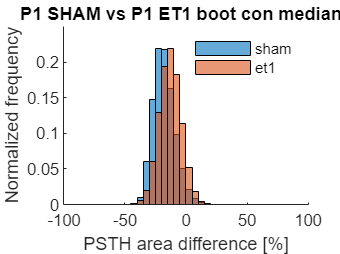

prob_boot_et1_p1_median=h_boot_et1_p1_median.Values;
hold off
xlim([-100 100])
title('P1 SHAM vs P1 ET1 boot con mediane')
xlabel('PSTH area difference [%]')
ylabel('Normalized frequency')
legend('sham', 'et1')
legend boxoff
box off

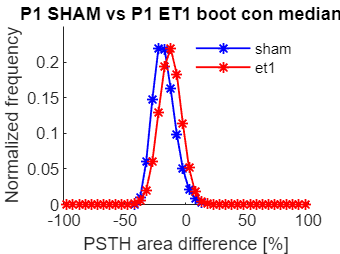


% istogramma lineare
figure
plot(x_axis_boot,prob_boot_sham_p1_median,'*','color','b',LineStyle='-',LineWidth=1)
hold on
plot(x_axis_boot,prob_boot_et1_p1_median,'*','color','r',LineStyle='-',LineWidth=1)
hold off
title('P1 SHAM vs P1 ET1 boot con mediane')
xlabel('PSTH area difference [%]')
ylabel('Normalized frequency')
box off
legend('sham','et1')
legend box off

## Confronto di boot di mediane di P2 in sham ed et1

h_boot_sham_p2_median=histogram(boot_sham(4,:),'Normalization','probability','BinWidth',bin_width_boot,'BinLimits',[-100 100])

h_boot_sham_p2_median =   Histogram with properties:

             Data: [-38.2022 -36.1082 -39.5537 -34.8543 -42.5204 -40.9052 -24.3079 -36.1082 -29.4923 -30.1510 -34.7339 -41.2049 -34.9746 -29.1226 -39.8534 -35.9547 -42.5204 -36.1082 -24.9380 -29.4923 -35.2676 -37.0989 -32.1131 -36.1082 -34.9746 … ]
           Values: [0 0 0 0 0 0 0 0 0 7.0000e-05 0.0025 0.0537 0.3713 0.2355 0.2038 0.0810 0.0457 0.0045 0.0018 1.2000e-04 1.0000e-05 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
          NumBins: 40
         BinEdges: [-100 -95 -90 -85 -80 -75 -70 -65 -60 -55 -50 -45 -40 -35 -30 -25 -20 -15 -10 -5 0 5 10 15 20 25 30 35 40 45 50 55 60 65 70 75 80 85 90 95 100]
         BinWidth: 5
        BinLimits: [-100 100]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show 

prob_boot_sham_p2_median=h_boot_sham_p2_median.Values;
hold on
h_boot_et1_p2_median=histogram(boot_et1(4,:),'Normalization','probability','BinWidth',bin_width_boot,'BinLimits',[-100 100])

h_boot_et1_p2_median =   Histogram with properties:

             Data: [-9.8562 -3.4713 -22.8400 1.6796 1.6796 -9.8562 17.3153 -5.1470 -16.6700 -1.0942 -4.8630 -1.0942 -58.9341 -22.8400 -4.8630 -3.6133 3.4681 -4.8630 -1.0942 -1.0942 13.0142 -8.3224 3.4681 -4.8630 16.0031 -2.6279 -2.6279 14.5086 … ]
           Values: [0 0 4.0000e-05 0.0054 0 0 0 1.5000e-04 0.0066 2.0000e-05 2.3000e-04 5.0000e-05 0.0168 0.0655 0.0100 0.0388 0.0669 0.0533 0.1503 0.2652 0.0910 0.0733 0.0773 0.0632 0.0144 0.0013 1.0000e-05 0 0 0 0 0 0 0 0 0 0 0 0 0]
          NumBins: 40
         BinEdges: [-100 -95 -90 -85 -80 -75 -70 -65 -60 -55 -50 -45 -40 -35 -30 -25 -20 -15 -10 -5 0 5 10 15 20 25 30 35 40 45 50 55 60 65 70 75 80 85 90 95 100]
         BinWidth: 5
        BinLimits: [-100 100]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show 

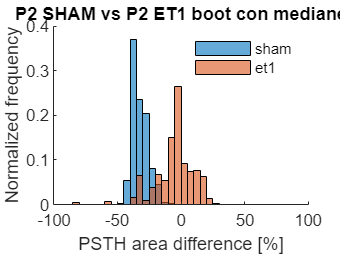

prob_boot_et1_p2_median=h_boot_et1_p2_median.Values;
hold off
xlim([-100 100])
title('P2 SHAM vs P2 ET1 boot con mediane')
xlabel('PSTH area difference [%]')
ylabel('Normalized frequency')
legend('sham', 'et1')
legend boxoff
box off

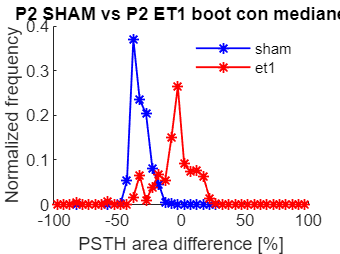


% istogramma lineare
figure
plot(x_axis_boot,prob_boot_sham_p2_median,'*','color','b',LineStyle='-',LineWidth=1)
hold on
plot(x_axis_boot,prob_boot_et1_p2_median,'*','color','r',LineStyle='-',LineWidth=1)
hold off
title('P2 SHAM vs P2 ET1 boot con mediane')
xlabel('PSTH area difference [%]')
ylabel('Normalized frequency')
box off
legend('sham','et1')
legend box off